# Simulation of Hybrid Electricity Model & Economic Dispatch

The Natural Gas Price model, Temperature model and Electricity Price hybrid model are jointly simulated to create market scenarios. Then, given a set of plant parameters and constraints a dispatch is performed on each set of simulated price paths to compute a set of daily cash-flows for each plant for each scenario (simulated path). The expected profit from the distribution of cash-flows and the 90% and 95% cash-flow-at-risk metrics are reported

## Load Models and Data

Import the required models (that have already been built), any required data (holidays) and set up the simulation parameters (date range and number of trials)

clear
tempModel = load('SavedModels\TemperatureModel')

tempModel = struct with fields:
           m: 50.8951
    sinmodel: [1×1 cfit]
     reglags: [1 2 3 4 23 24 25 47 48 49]
      arimax: [1×1 arima]
    lastDate: 11/30/2018
        Freq: 'hourly'


NGModel = load('SavedModels\NGPriceModel')

NGModel = struct with fields:
     oumodel: [1×1 hwv]
          dt: 0.0038
      simFcn: @(NSteps,NTrials)exp(squeeze(simulate(OUmodel,NSteps,'NTrials',NTrials,'DeltaTime',dt)))
    lastDate: 15-Jan-2019 00:00:00
        Freq: 'daily'
        Data: [5565×1 timetable]


elecModel = load('SavedModels\ElectricityModel')

elecModel = struct with fields:
    treemodel: [1×1 struct]
      reglags: [1 2 3 4 23 24 25 48]
       arimax: [1×1 arima]
     lastDate: 11/30/2018
         Freq: 'hourly'


startDate = datetime('2018-11-30 00:00:00','InputFormat','yyy-MM-dd HH:mm:ss');
endDate = datetime('2019-12-31 23:00:00','InputFormat','yyy-MM-dd HH:mm:ss');
Dates = startDate:hours:endDate;

hdays = holidays(min(Dates),max(Dates));

NTrials = 500;
NSteps = length(Dates);

## Perform Simulation

### Step 1: Simulate Natural Gas

Natural gas model is a daily model and we have data points past the start date of November 30, 2018.  We will need add the real data in and simulate out the remainder of the year  The simulateNG function does this.

SimNG = simulateNG(startDate,endDate,NGModel,NTrials);

retime to hourly

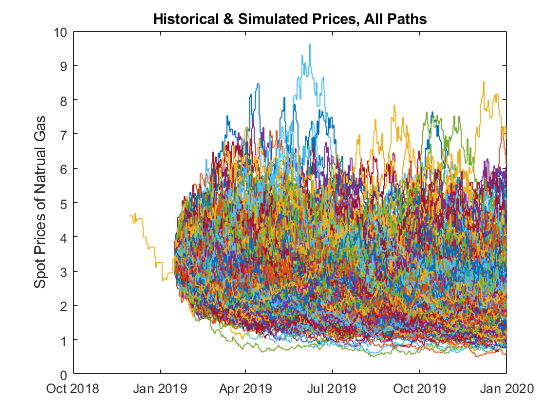

SimNG = retime(SimNG,'hourly','previous');

plot(SimNG.Dates,SimNG.Variables)
ylabel('Spot Prices of Natrual Gas')
title('Historical & Simulated Prices, All Paths');

### Step 2: Simulate Temperatures

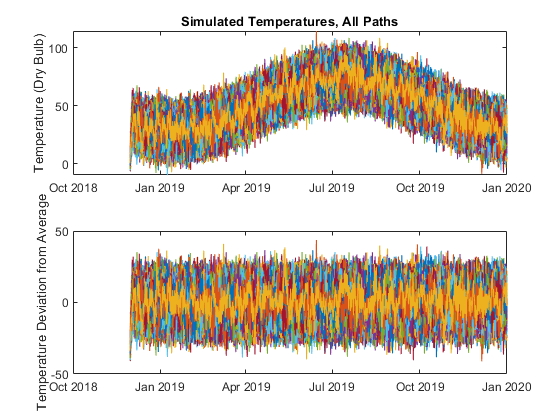

[SimTemp, SimTempDeviation] = simulateTemperatures(tempModel,Dates,NTrials);

figure
subplot(2,1,1)
plot(SimTemp.Dates,SimTemp.Variables)
ylabel('Temperature (Dry Bulb)')
title('Simulated Temperatures, All Paths');

subplot(2,1,2)
plot(SimTempDeviation.Dates, SimTempDeviation.Variables)
ylabel('Temperature Deviation from Average')

### Step 3: Simulate Electricity

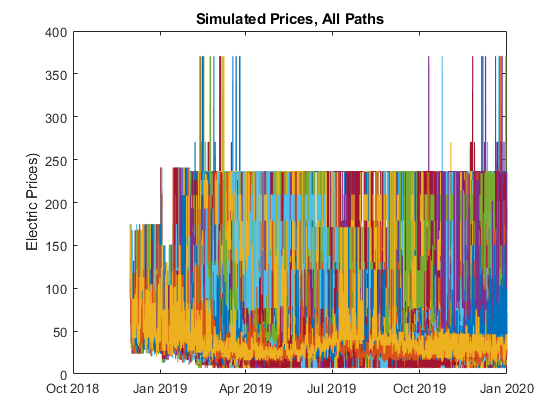

[SimElec, X] = simulateElecPrices(SimTemp, SimTempDeviation, SimNG, hdays, elecModel, NSteps, NTrials);

figure
plot(SimElec.Dates,SimElec.Variables)   
ylabel('Electric Prices)')
title('Simulated Prices, All Paths');

## Define Power Plant Characteristics

Define the operating characteristics of a gas-fired plant.

capacity = 100; % MW
heatRate = 8500; % Btu/KWh
VOMCosts = 3; % $/MWh
minRun   = 12; % hrs/day

## Compute Optimal Dispatch for Single Path

For a chosen simulated path, the function *dispatch* is used to compute the optimal daily dispatch decisions for the power plant and to return a series of cashflows and operational statistics. Individual cash-flows are displayed in a stem plot.

path = 1;
[profit, numOpDays, aveHrs, pctRun, earnings] = ...
   dispatch(capacity, heatRate, VOMCosts, minRun, SimElec{:,path}, SimNG{:,path});

disp(['Path ' int2str(path) ' results:']);

Path 1 results:


fprintf('Profit: $%0.4f M\nOperating Days: %d\nAverage Hours per Operating Day: %0.2f\nPercentage of Time Running: %0.2f%%\n\n\n',...
    profit/1e6, numOpDays, aveHrs, pctRun*100);

Profit: $26.0348 M
Operating Days: 389
Average Hours per Operating Day: 20.98
Percentage of Time Running: 85.67%




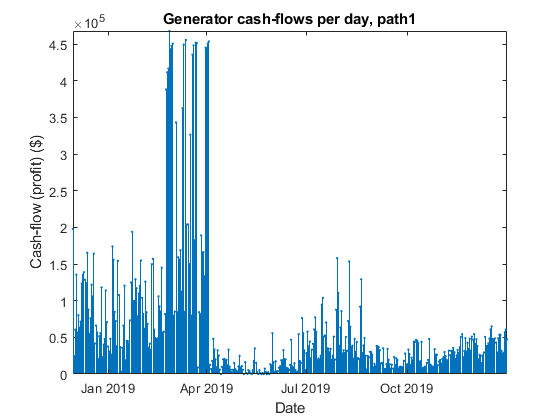


figure
stem(Dates(1:24:end), earnings*capacity, 'fill', 'Markersize', 5, 'Marker', '.');
axis tight;
xlabel('Date'); ylabel('Cash-flow (profit) ($)');
title(['Generator cash-flows per day, path' int2str(path)]);

## Compute Optimal Dispatch for All Paths

The same *dispatch* function can be used to generate total profit and operation statistics for all simulated natural gas and electricity price paths. The distribution of the resulting profits or total cash-flows can be analyzed to compute expected cash-flow and cash-flow-at-risk.

profit    = zeros(1,NTrials);
numOpDays = zeros(1,NTrials);
aveHrs    = zeros(1,NTrials);
pctRun    = zeros(1,NTrials);

for path = 1:NTrials
    [profit(path), numOpDays(path), aveHrs(path), pctRun(path)] =...
        dispatch(capacity, heatRate, VOMCosts, minRun, SimElec{:,path}, SimNG{:,path});
end

expProfit = mean(profit);
numOpDays = mean(numOpDays);
aveHrs    = mean(aveHrs);
pctRun    = mean(pctRun);
% Compute 90% and 95% Cash-flow-at-Risk
CFaR = expProfit - prctile(profit, [10 5]); 

disp('Simulation Averages/Expectations');

Simulation Averages/Expectations


fprintf(['Operating Days: %0.2f\nAverage Hours per Operating Day: %0.2f\n' ... 
    'Percentage of Time Running: %0.2f%%\nExpected Profit: $%0.4f M\n' ...
    '90%% Cash-flow-at-Risk: $%0.4f M\n95%% Cash-flow-at-Risk: $%0.4f M\n'],...
    numOpDays, aveHrs, pctRun*100, expProfit/1e6, CFaR(1)/1e6, CFaR(2)/1e6);

Operating Days: 383.22
Average Hours per Operating Day: 19.79
Percentage of Time Running: 79.64%
Expected Profit: $17.7550 M
90% Cash-flow-at-Risk: $4.2614 M
95% Cash-flow-at-Risk: $4.7735 M


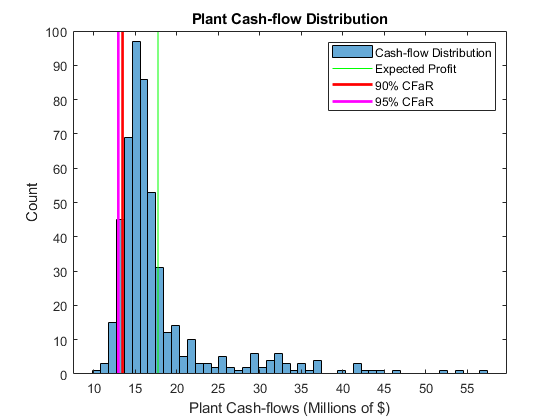


figure;
histogram(profit/1e6,50);
line(expProfit*[1 1]/1e6, ylim, 'Color', 'g');
line((expProfit-CFaR(1))*[1 1]/1e6, ylim, 'Color', 'r', 'LineWidth', 2);
line((expProfit-CFaR(2))*[1 1]/1e6, ylim, 'Color', 'm', 'LineWidth', 2);
legend('Cash-flow Distribution', 'Expected Profit', '90% CFaR', '95% CFaR')
xlabel('Plant Cash-flows (Millions of $)');
ylabel('Count');
title('Plant Cash-flow Distribution');